# Wheel Running Gait Analysis (Full Pipeline)

Combines the per-file gait analysis, the nose-tail normalization, and the group compiler into one script.

Ingestion is driven by the manifest CSV, which needs only a FilePath and an AuthorsNote column; the ID is derived from the filename. The Author's Note also selects the frame window ("150 DPI" and "LDOPA" trials are windowed).

Outputs one table containing every normalized metric plus the per-frame stride counts, then plots each metric grouped by Author's Note.

## Configuration

% Paths are relative to the Current Folder, which must be this script folder.
manifestPath = "filepaths.csv"; % needs a FilePath and an AuthorsNote column
outputPath = "results.csv";

fps = 100;

threshold_pawSpeed = 10; % pixels per frame
threshold_similarSpeed = 5; % pixels per frame
threshold_similarAngle = 1; % rad
threshold_wheelOn = 0.1; % speed of wheel in pixels per frame

diagnosticRows = [1]; % manifest row numbers to render gait/speed figures for, e.g. [19 22]
diagnosticRange = 1000:2000; % frames shown in those figures

## Ingest Manifest

Only FilePath and AuthorsNote are read; the ID is derived from the filename. Columns are matched by name, so any extra columns in the file are ignored and the column order does not matter.

% The delimiter is pinned: with few columns, autodetection picks the backslash in
% the Windows paths over the comma and silently mangles the file.
manifest = readtable(manifestPath, "TextType", "string", "VariableNamingRule", "preserve", ...
    "Delimiter", ",");

required = ["FilePath", "AuthorsNote"];
isPresent = ismember(required, string(manifest.Properties.VariableNames));
if ~all(isPresent)
    error("%s is missing required column(s): %s", manifestPath, strjoin(required(~isPresent), ", "));
end

filePath = string(manifest.FilePath);
authorNote = string(manifest.AuthorsNote);

% ID is the leading digits of the filename (1715\1715_20260617_... -> 1715).
[~, baseName] = arrayfun(@(p) fileparts(p), filePath, "UniformOutput", false);
id = str2double(regexp(string(baseName), "^\d+", "match", "once"));

unparsed = isnan(id);
if any(unparsed)
    warning("%d file(s) do not start with an ID and will not match a genotype:\n%s", ...
        sum(unparsed), strjoin("  " + filePath(unparsed), newline));
end

numFiles = numel(filePath);

% Manifest paths are relative to the Current Folder; absolute (legacy) paths are remapped.
resolvedPath = resolvePath(filePath);

missing = ~arrayfun(@isfile, resolvedPath);
if any(missing)
    warning("%d manifest file(s) not found and will be skipped:\n%s", ...
        sum(missing), strjoin("  " + filePath(missing), newline));
end

fprintf("Manifest: %d file(s), %d found.\n", numFiles, sum(~missing));

Manifest: 96 file(s), 96 found.


## Import Options for DeepLabCut Position Files

posOpts = delimitedTextImportOptions("NumVariables", 19);
posOpts.DataLines = [4, Inf];
posOpts.Delimiter = ",";
posOpts.VariableNames = ["scorer", "DLC_resnet50_WheelRunningProjectAug6shuffle1_60000", "DLC_resnet50_WheelRunningProjectAug6shuffle1_1", "DLC_resnet50_WheelRunningProjectAug6shuffle1_2", "DLC_resnet50_WheelRunningProjectAug6shuffle1_3", "DLC_resnet50_WheelRunningProjectAug6shuffle1_4", "DLC_resnet50_WheelRunningProjectAug6shuffle1_5", "DLC_resnet50_WheelRunningProjectAug6shuffle1_6", "DLC_resnet50_WheelRunningProjectAug6shuffle1_7", "DLC_resnet50_WheelRunningProjectAug6shuffle1_8", "DLC_resnet50_WheelRunningProjectAug6shuffle1_9", "DLC_resnet50_WheelRunningProjectAug6shuffle1_10", "DLC_resnet50_WheelRunningProjectAug6shuffle1_11", "DLC_resnet50_WheelRunningProjectAug6shuffle1_12", "DLC_resnet50_WheelRunningProjectAug6shuffle1_13", "DLC_resnet50_WheelRunningProjectAug6shuffle1_14", "DLC_resnet50_WheelRunningProjectAug6shuffle1_15", "DLC_resnet50_WheelRunningProjectAug6shuffle1_16", "DLC_resnet50_WheelRunningProjectAug6shuffle1_17"];
posOpts.VariableTypes = repmat("double", 1, 19);
posOpts.ExtraColumnsRule = "ignore";
posOpts.EmptyLineRule = "read";

## Analyze Every File

Per file: read positions, apply the Author's Note frame window, derive paw vectors and gait, suppress swings that move with the wheel, then compute the Sheppard et al. metrics. Lengths are divided by that file's mean nose-tail distance (measured over the same window) so they are body-length normalized.

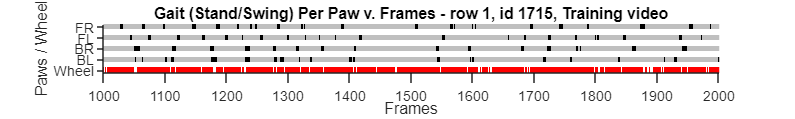

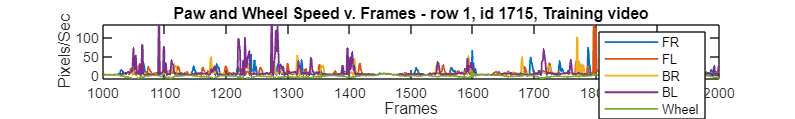

[  1/ 96] Training video id 1715   231517 frames, nose-tail 403.5 px
[  2/ 96] Training video id 1715   199560 frames, nose-tail 404.7 px
[  3/ 96] Training video id 1715   152292 frames, nose-tail 357.9 px
[  4/ 96] Training video id 1715   135082 frames, nose-tail 324.1 px
[  5/ 96] Training video id 1715   121641 frames, nose-tail 401.5 px
[  6/ 96] 60 DPI    id 1715   132618 frames, nose-tail 376.7 px
[  7/ 96] Training video id 1716   143449 frames, nose-tail 377.3 px
[  8/ 96] Training video id 1716   144448 frames, nose-tail 389.3 px
[  9/ 96] Training video id 1716   121332 frames, nose-tail 400.6 px
[ 10/ 96] Training video id 1716   133426 frames, nose-tail 432.3 px
[ 11/ 96] Training video id 1716   121092 frames, nose-tail 402.9 px
[ 12/ 96] 60 DPI    id 1716   133167 frames, nose-tail 368.1 px
[ 13/ 96] Training video id 1777   127499 frames, nose-tail 413.3 px
[ 14/ 96] Training video id 1777   132906 frames, nose-tail 407.1 px
[ 15/ 96] Training video id 1777   132114 fr

metricNames = ["StrideSpeed", ...
    "StrideLengthFR", "StepLengthFR", "StepWidthFR", ...
    "StrideLengthFL", "StepLengthFL", "StepWidthFL", ...
    "StrideLengthBR", "StepLengthBR", "StepWidthBR", ...
    "StrideLengthBL", "StepLengthBL", "StepWidthBL", ...
    "TemporalSymmetryF", "TemporalSymmetryB", ...
    "DutyFactorF", "DutyFactorB", ...
    "AngularVelocity", ...
    "NoseLateralDisplacementBR", "NoseLateralDisplacementPhaseOffsetBR", ...
    "TailLateralDisplacementBR", "TailLateralDisplacementPhaseOffsetBR", ...
    "StrideCountPerFrameFR", "StrideCountPerFrameFL", "StrideCountPerFrameBR", "StrideCountPerFrameBL"];

% Length metrics scaled by mean nose-tail distance; rates and ratios are not.
normalizedNames = ["StrideLengthFR", "StepLengthFR", "StepWidthFR", ...
    "StrideLengthFL", "StepLengthFL", "StepWidthFL", ...
    "StrideLengthBR", "StepLengthBR", "StepWidthBR", ...
    "StrideLengthBL", "StepLengthBL", "StepWidthBL", ...
    "NoseLateralDisplacementBR", "TailLateralDisplacementBR"];

metrics = nan(numFiles, numel(metricNames));
noseTailLength = nan(numFiles, 1);
analyzedFrames = nan(numFiles, 1);

for f = 1:numFiles
    if missing(f)
        continue
    end

    pos = readtable(resolvedPath(f), posOpts);
    pos = applyFrameWindow(pos, authorNote(f), fps);

    numFrames = size(pos, 1);
    analyzedFrames(f) = numFrames;

    if numFrames < 3
        warning("Row %d has only %d frame(s) after windowing; skipped.", f, numFrames);
        continue
    end

    fr_pos = pos{:, 5:7};
    nose_pos = pos{:, 2:4};
    fl_pos = pos{:, 8:10};
    br_pos = pos{:, 11:13};
    bl_pos = pos{:, 14:16};
    tail_pos = pos{:, 17:19};

    fr_vector = calculateVector(fr_pos);
    fl_vector = calculateVector(fl_pos);
    br_vector = calculateVector(br_pos);
    bl_vector = calculateVector(bl_pos);

    fr_gait = calculateGait(fr_vector)';
    fl_gait = calculateGait(fl_vector)';
    br_gait = calculateGait(br_vector)';
    bl_gait = calculateGait(bl_vector)';

    gait = [fr_gait, fl_gait, br_gait, bl_gait];
    speed = [fr_vector(:, 3), fl_vector(:, 3), br_vector(:, 3), bl_vector(:, 3)];
    angle = [fr_vector(:, 4), fl_vector(:, 4), br_vector(:, 4), bl_vector(:, 4)];

    % Paws moving with a similar vector are riding the wheel, not swinging.
    angle2 = changeRadiansInterval(angle); % [-pi, pi] -> [0, 2pi)

    similarVectors = false(numFrames, 4);
    for i = 1:4
        for j = i + 1:4
            diffSpeed = abs(speed(:, i) - speed(:, j));

            diffAngle = abs(angle2(:, i) - angle2(:, j));

            isSimilar = diffSpeed < threshold_similarSpeed & diffAngle < threshold_similarAngle & abs(speed(:, i)) < 15 & abs(speed(:, j)) < 15;

            similarVectors(:, i) = similarVectors(:, i) | isSimilar;
            similarVectors(:, j) = similarVectors(:, j) | isSimilar;
        end
    end

    filteredGait = gait;
    filteredGait(similarVectors & gait == "swing") = "stand";
    filteredGait(speed < threshold_pawSpeed) = "stand"; % too slow to be a swing
    [fr_filteredGait, fl_filteredGait, br_filteredGait, bl_filteredGait] = ...
        deal(filteredGait(:, 1), filteredGait(:, 2), filteredGait(:, 3), filteredGait(:, 4));

    % NaN, not 0, marks a paw that is not riding: no measurement rather than a
    % measured zero, so it cannot be picked up by a min/max/mean over the paws.
    wheelSpeed = nan(numFrames, 4);
    wheelSpeed(similarVectors) = speed(similarVectors);

    % Signed: motion pointing backwards along the wheel is negative.
    isReverse = angle2 > pi / 2 & angle2 < 3 * pi / 2;
    wheelSpeed(isReverse) = -wheelSpeed(isReverse);

    % One signed wheel speed per frame, averaged over the paws that are riding.
    % They agree within threshold_similarSpeed by construction, so the mean is
    % over values already constrained to be close. NaN where no paw is riding.
    wheelSpeedFrame = mean(wheelSpeed, 2, 'omitnan');

    % Metrics based on Sheppard et al.
    % A frame with no wheel motion is a genuine zero, so it counts in the mean.
    strideSpeed = mean(fillmissing(wheelSpeedFrame, 'constant', 0));

    [~, fr_strideCount, fr_strideLength, ~, fr_stepLength, fr_stepWidth] = calculateStrideLength(fr_filteredGait, fr_pos, fl_pos);
    [~, fl_strideCount, fl_strideLength, ~, fl_stepLength, fl_stepWidth] = calculateStrideLength(fl_filteredGait, fl_pos, fr_pos);
    [~, br_strideCount, br_strideLength, ~, br_stepLength, br_stepWidth] = calculateStrideLength(br_filteredGait, br_pos, bl_pos);
    [~, bl_strideCount, bl_strideLength, ~, bl_stepLength, bl_stepWidth] = calculateStrideLength(bl_filteredGait, bl_pos, br_pos);

    [fr_standDutyFactor, ~] = calculateDutyFactor(fr_filteredGait);
    [fl_standDutyFactor, ~] = calculateDutyFactor(fl_filteredGait);
    [br_standDutyFactor, ~] = calculateDutyFactor(br_filteredGait);
    [bl_standDutyFactor, ~] = calculateDutyFactor(bl_filteredGait);

    front_temporalSymmetry = calculateTemporalSymmetry(fl_standDutyFactor, fr_standDutyFactor); % stand only
    back_temporalSymmetry = calculateTemporalSymmetry(bl_standDutyFactor, br_standDutyFactor);

    front_dutyFactor = (fr_standDutyFactor + fl_standDutyFactor) / 2; % percentage time where paw on the ground
    back_dutyFactor = (bl_standDutyFactor + br_standDutyFactor) / 2;

    dx_noseTail = nose_pos(:, 1) - tail_pos(:, 1);
    dy_noseTail = nose_pos(:, 2) - tail_pos(:, 2);

    noseTail_angle = atan2(dy_noseTail, dx_noseTail);
    angularVelocity = mean(gradient(noseTail_angle), 'all'); % radians per frame

    % Lateral displacement and phase offset relative to back right stride cycles (pixels)
    [br_noseLateralDisplacement, br_noseLateralDisplacementPhaseOffset] = calculateLateralDisplacement(br_filteredGait, nose_pos);
    [br_tailLateralDisplacement, br_tailLateralDisplacementPhaseOffset] = calculateLateralDisplacement(br_filteredGait, tail_pos);

    row = [strideSpeed, ...
        fr_strideLength, fr_stepLength, fr_stepWidth, ...
        fl_strideLength, fl_stepLength, fl_stepWidth, ...
        br_strideLength, br_stepLength, br_stepWidth, ...
        bl_strideLength, bl_stepLength, bl_stepWidth, ...
        front_temporalSymmetry, back_temporalSymmetry, ...
        front_dutyFactor, back_dutyFactor, ...
        angularVelocity, ...
        br_noseLateralDisplacement, br_noseLateralDisplacementPhaseOffset, ...
        br_tailLateralDisplacement, br_tailLateralDisplacementPhaseOffset, ...
        fr_strideCount / numFrames, fl_strideCount / numFrames, ...
        br_strideCount / numFrames, bl_strideCount / numFrames];

    % Normalize lengths by this file's mean nose-tail distance over the same window.
    noseTail = vecnorm(nose_pos(:, 1:2) - tail_pos(:, 1:2), 2, 2);
    noseTailLength(f) = mean(noseTail, "omitnan");

    isNormalized = ismember(metricNames, normalizedNames);
    row(isNormalized) = row(isNormalized) ./ noseTailLength(f);

    metrics(f, :) = row;

    if ismember(f, diagnosticRows)
        plotGaitRaster(filteredGait, similarVectors, speed, diagnosticRange, threshold_wheelOn, f, id(f), authorNote(f));
        plotSpeed(speed, wheelSpeedFrame, diagnosticRange, f, id(f), authorNote(f));
    end

    fprintf("[%3d/%3d] %-9s id %-5d %7d frames, nose-tail %.1f px\n", ...
        f, numFiles, authorNote(f), id(f), numFrames, noseTailLength(f));
end

## Assemble and Write Results

results = table(filePath, id, authorNote, 'VariableNames', {'FilePath', 'ID', 'AuthorsNote'});
results = [results, array2table(metrics, 'VariableNames', metricNames)];

writetable(results, outputPath);
fprintf("Wrote %d row(s) to %s\n", height(results), outputPath);

Wrote 96 row(s) to results.csv



results

results = 96×29 table
                                                      FilePath                                                        ID       AuthorsNote       StrideSpeed    StrideLengthFR    StepLengthFR    StepWidthFR    StrideLengthFL    StepLengthFL    StepWidthFL    StrideLengthBR    StepLengthBR    StepWidthBR    StrideLengthBL    StepLengthBL    StepWidthBL    TemporalSymmetryF    TemporalSymmetryB    DutyFactorF    DutyFactorB    AngularVelocity    NoseLateralDisplacementBR    NoseLateralDisplacementPhaseOffsetBR    TailLateralDisplacementBR    TailLateralDispla

## Compare Metrics Across Groups

Joins the genotype sheet onto the results by ID, then plots every metric as a boxchart grouped by Author's Note, one figure per genotype.

opts = spreadsheetImportOptions("NumVariables", 6);
opts.Sheet = "Genotype";
opts.DataRange = "A2"; % open-ended: reads to the end of the sheet, so new animals are picked up
opts.VariableNames = ["Tag", "Sex", "Genotype", "DOB", "Month", "Injections"];
opts.VariableTypes = ["double", "categorical", "categorical", "datetime", "datetime", "datetime"];
opts = setvaropts(opts, ["Sex", "Genotype"], "EmptyFieldRule", "auto");

genotype = readtable("NP recording file list.xlsx", opts, "UseExcel", false);

clear opts

% Metric columns are captured before the join, which appends the sheet's own columns.
vars = results.Properties.VariableNames(4:end);

data = innerjoin(results, genotype, "LeftKeys", "ID", "RightKeys", "Tag");
data.AuthorsNote = categorical(data.AuthorsNote);

fprintf("Genotype join: %d of %d result row(s) matched a tag.\n", height(data), height(results));

Genotype join: 96 of 96 result row(s) matched a tag.


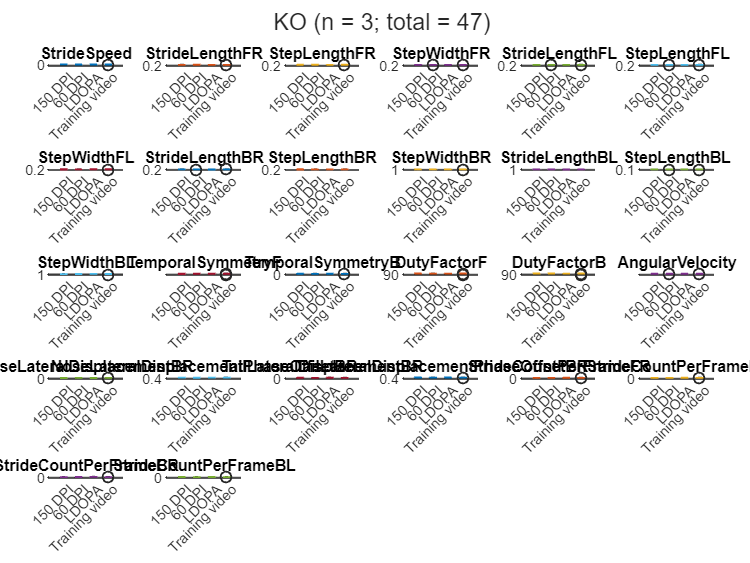

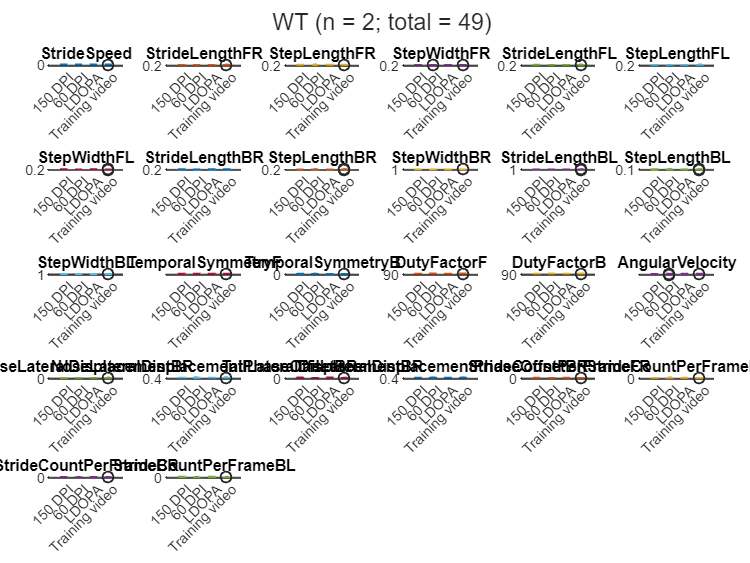


genotypes = categories(removecats(data.Genotype));
metricColors = lines(numel(vars));

varYLim = cell(size(vars));

for i = 1:numel(vars)
    y = data{:, vars{i}};
    ymin = min(y, [], "omitnan");
    ymax = max(y, [], "omitnan");

    pad = 0.05 * (ymax - ymin);
    if pad == 0
        pad = 1;
    end

    varYLim{i} = [ymin - pad, ymax + pad];
end

for k = 1:numel(genotypes)
    inGenotype = data.Genotype == genotypes{k};
    group = removecats(data.AuthorsNote(inGenotype));

    figure
    tiledlayout("flow", "TileSpacing", "compact", "Padding", "compact")

     for i = 1:numel(vars)
        nexttile

        b = boxchart(group, data{inGenotype, vars{i}});
        b.BoxFaceColor = metricColors(i, :);
        b.MarkerColor = [0.15 0.15 0.15];
        b.WhiskerLineColor = [0.25 0.25 0.25];

        ylim(varYLim{i})   % same y-axis for this metric across genotypes

        title(vars{i}, "Interpreter", "none")
        xtickangle(45)
        grid on
    end

    numDrugWindow = [sum(inGenotype & data.AuthorsNote == "150 DPI"), ...
        sum(inGenotype & data.AuthorsNote == "LDOPA")];

    if numDrugWindow(1) ~= numDrugWindow(2)
        warning("%s: %d '150 DPI' row(s) but %d 'LDOPA' row(s); expected a matched pair per session.", ...
            genotypes{k}, numDrugWindow(1), numDrugWindow(2));
    end

    sgtitle(sprintf("%s (n = %d; total = %d)", ...
    genotypes{k}, max(numDrugWindow), sum(inGenotype)))
end


data

data = 96×34 table
                                                      FilePath                                                       ID      AuthorsNote      StrideSpeed    StrideLengthFR    StepLengthFR    StepWidthFR    StrideLengthFL    StepLengthFL    StepWidthFL    StrideLengthBR    StepLengthBR    StepWidthBR    StrideLengthBL    StepLengthBL    StepWidthBL    TemporalSymmetryF    TemporalSymmetryB    DutyFactorF    DutyFactorB    AngularVelocity    NoseLateralDisplacementBR    NoseLateralDisplacementPhaseOffsetBR    TailLateralDisplacementBR    TailLateralDisplacement

## Functions

function resolved = resolvePath(rawPath)
    % Accepts a path that already resolves, or a stale absolute path whose
    % trailing <folder>/<file> still sits in the Current Folder.
    resolved = rawPath;

    for k = 1:numel(rawPath)
        p = rawPath(k);

        if isfile(p)
            continue
        end

        parts = split(replace(p, "/", filesep), filesep);
        if numel(parts) >= 2
            candidate = fullfile(parts(end - 1), parts(end));
            if isfile(candidate)
                resolved(k) = candidate;
            end
        end
    end
end

function pos = applyFrameWindow(pos, authorNote, fps)
    % The Author's Note selects the analysis window for the drug trials.
    switch authorNote
        case "150 DPI"
            lastFrame = min(fps * 60 * 20, size(pos, 1));
            pos = pos(1:lastFrame, :);
        case "LDOPA"
            firstFrame = min(fps * 3000, size(pos, 1));
            lastFrame = min(fps * 4200, size(pos, 1));
            pos = pos(firstFrame:lastFrame, :);
    end
end

function vector = calculateVector(pos)
    pos_x = pos(:, 1);
    pos_y = pos(:, 2);

    dx = gradient(pos_x);
    dy = gradient(pos_y);

    speed = sqrt(dx.^2 + dy.^2); % pixels per frame
    angle = atan2(dy, dx);

    vector = [dx, dy, speed, angle];
end

function gait = calculateGait(vector) % dir only, no mag; single column stand/swing
    angle = vector(:, 4);
    gait = strings(size(angle))';

    gait(isnan(angle)) = NaN;
    gait(angle <= pi / 2 & angle >= -pi / 2) = "swing";
    gait(angle >= pi / 2 | angle <= -pi / 2) = "stand";
end

function outputAngle = changeRadiansInterval(inputAngle) % change angle interval in radians from [-pi, pi] to [0, 2pi)
    outputAngle = inputAngle;
    outputAngle(inputAngle < 0) = 2 * pi + inputAngle(inputAngle < 0);
end

function [strideTotalLength, strideCount, strideLength, stepDistance, stepLength, stepWidth] = calculateStrideLength(gait, pos, opposite_pos)
    strideTotalLength = 0;
    strideCount = 0;

    stepTotalLength = 0;
    stepTotalWidth = 0;

    pos_1 = [];
    pos_2 = [];
    pos_3 = []; % for step

    if gait(1) == "swing"
        pos_1 = pos(1, :);
    end

    for i = 2:numel(gait) - 1
        if gait(i) == "swing" && gait(i - 1) == "stand"
            pos_1 = pos(i, :);
        end

        if gait(i) == "swing" && gait(i + 1) == "stand"
            pos_2 = pos(i, :);
            strideTotalLength = strideTotalLength + norm(pos_1(1:2) - pos_2(1:2));

            pos_3 = opposite_pos(i, :);
            % x is the fore-aft axis (nose-tail lies along x), y is lateral.
            stepTotalLength = stepTotalLength + abs(pos_1(1) - pos_3(1));
            stepTotalWidth = stepTotalWidth + abs(pos_1(2) - pos_3(2));

            pos_1 = [];
            pos_2 = [];
            pos_3 = [];
            strideCount = strideCount + 1;
        end
    end

    if ~isempty(pos_1)
        pos_2 = pos(end, :);
        strideTotalLength = strideTotalLength + norm(pos_1(1:2) - pos_2(1:2));

        pos_3 = opposite_pos(end, :);
        stepTotalLength = stepTotalLength + abs(pos_1(1) - pos_3(1));
        stepTotalWidth = stepTotalWidth + abs(pos_1(2) - pos_3(2));

        strideCount = strideCount + 1;
    end

    strideLength = strideTotalLength / strideCount;
    stepLength = stepTotalLength / strideCount;
    stepWidth = stepTotalWidth / strideCount;
    stepDistance = sqrt(stepWidth^2 + stepLength^2);
end

function [standDutyFactor, swingDutyFactor] = calculateDutyFactor(gait)
    numFramesStand = sum(gait == "stand", 'all');
    standDutyFactor = numFramesStand / numel(gait) * 100; % percent
    swingDutyFactor = 100 - standDutyFactor;
end

function temporalSymmetry = calculateTemporalSymmetry(leftDutyFactor, rightDutyFactor)
    temporalSymmetry = (leftDutyFactor - rightDutyFactor) / (leftDutyFactor + rightDutyFactor);
end

function [lateralDisplacement, lateralDisplacementPhaseOffset] = calculateLateralDisplacement(gait, pos)
    lateralDisplacement = 0;
    lateralDisplacementPhaseOffset = 0;

    startFrame = 0;
    endFrame = 0;

    strideCycle = false; % stride cycle is swing + stand

    strideCount = 0;

    if gait(1) == "swing" % assuming swing + stand as stride cycle, inverse for stand + swing
        startFrame = 1;
        strideCycle = true;
    end

    for i = 2:numel(gait) - 1
        if gait(i) == "swing" && gait(i - 1) == "stand" % assuming swing + stand as stride cycle, inverse for stand + swing
            if strideCycle
                endFrame = i - 1;

                strideFrame = pos(startFrame:endFrame, 2);

                [yMax, idy] = max(strideFrame);

                lateralDisplacementPhaseOffset = lateralDisplacementPhaseOffset + idy / numel(strideFrame);
                lateralDisplacement = lateralDisplacement + (yMax - min(strideFrame));

                startFrame = 0;
                endFrame = 0;

                strideCount = strideCount + 1;

                strideCycle = false;
            else
                startFrame = i;

                strideCycle = true;
            end
        end
    end

    lateralDisplacement = lateralDisplacement / strideCount;
    lateralDisplacementPhaseOffset = lateralDisplacementPhaseOffset / strideCount;
end

function plotGaitRaster(gait, similarVectors, speed, range, threshold_wheelOn, rowNumber, id, authorNote)
    % Paws: stand = gray, swing = black. Wheel: off = white, on = red.
    range = range(range >= 1 & range <= size(gait, 1));
    if isempty(range)
        return
    end

    gaitNumeric = zeros(size(gait));
    gaitNumeric(gait == "swing") = 1;

    wheelOn = any(similarVectors, 2);
    wheelOn(min(speed, [], 2) < threshold_wheelOn) = false; % a paw can be raised while the wheel spins

    img = ones(9, numel(range), 3);
    rowMap = [1, 3, 5, 7];

    for p = 1:4
        row = rowMap(p);

        img(row, :, :) = 0.75;

        swingFrames = gaitNumeric(range, p)' == 1;

        img(row, swingFrames, :) = 0.00;
    end

    wheelFrames = wheelOn(range)';

    img(9, :, :) = 1.00;
    img(9, wheelFrames, 1) = 1.00;
    img(9, wheelFrames, 2) = 0.00;
    img(9, wheelFrames, 3) = 0.00;

    figure('Color', 'w', 'Position', [0 0 2000 300]);
    image(range, 1:9, img);

    title(sprintf('Gait (Stand/Swing) Per Paw v. Frames - row %d, id %d, %s', rowNumber, id, authorNote));
    xlabel('Frames');
    ylabel('Paws / Wheel');

    yticks([1 3 5 7 9]);
    yticklabels({'FR', 'FL', 'BR', 'BL', 'Wheel'});

    set(gca, 'TickDir', 'out', 'Box', 'off');
end

function plotSpeed(speed, wheelSpeedFrame, range, rowNumber, id, authorNote)
    range = range(range >= 1 & range <= size(speed, 1));
    if isempty(range)
        return
    end

    figure('Color', 'w', 'Position', [0 0 2000 300]);
    plot(range, speed(range, :), LineWidth = 1);
    hold on
    plot(range, wheelSpeedFrame(range), LineWidth = 1)

    title(sprintf('Paw and Wheel Speed v. Frames - row %d, id %d, %s', rowNumber, id, authorNote));
    xlabel('Frames');
    ylabel('Pixels/Sec');

    legend({'FR', 'FL', 'BR', 'BL', 'Wheel'})
end